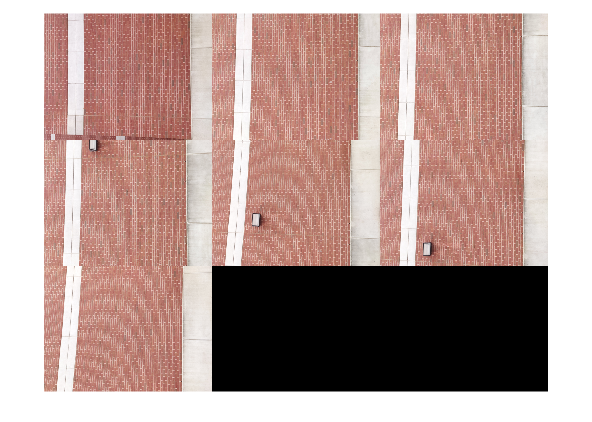

% Load images.
buildingDir = fullfile("C:\Users\nobel\Downloads\LAB 5","Brick_Wall");
buildingScene = imageDatastore(buildingDir);
montage(buildingScene.Files)

I = imrotate(readimage(buildingScene,1),270);
grayImage = im2gray(I);

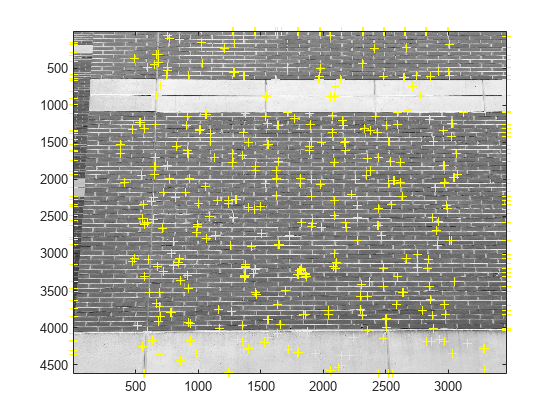

%Harris corner detection:
harris(grayImage,500,'disp','tile',[10 10]);

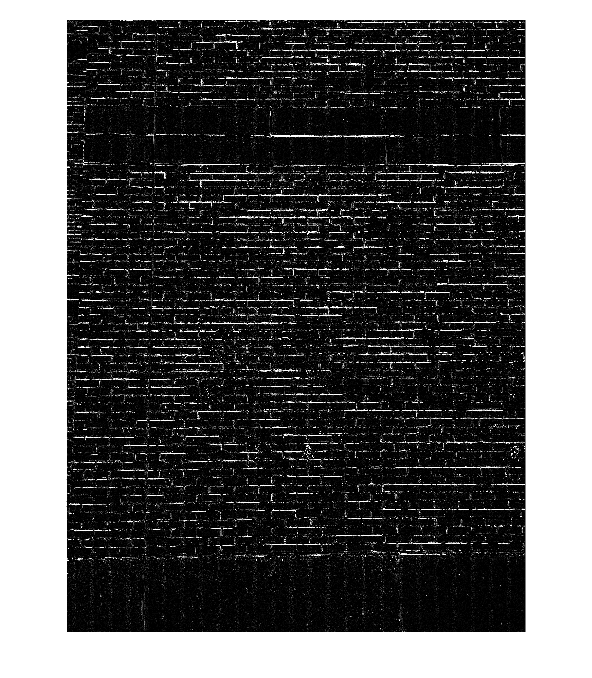

% Convolve2 With Edge detection matrix
dx = [-1 -1 -1; -1 8 -1;-1 -1 -1]/100;
output = convolve2(grayImage,dx,'full');
imshow(output)

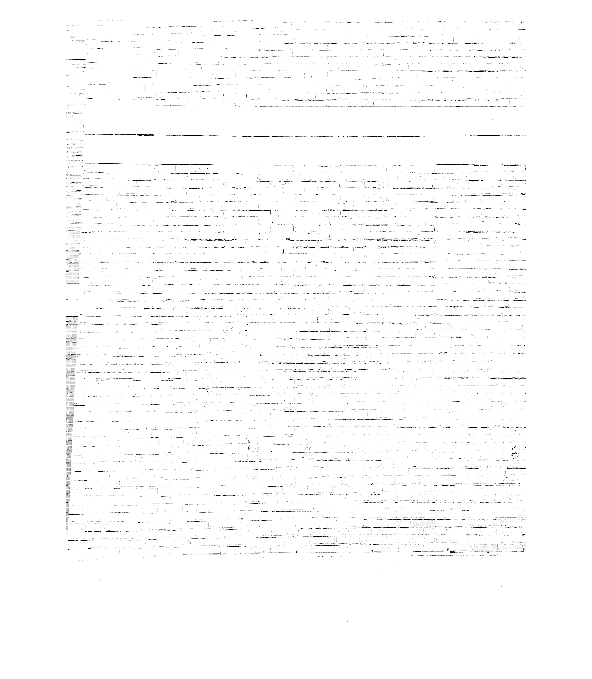

%Convolve2 with sharpening matrix
dx = [0 -1 0; -1 5 -1; 0 -1 0]/100;
output = convolve2(grayImage,dx,'same');
imshow(output)

%Mosiac
% Read the first image from the image set.
I = readimage(buildingScene,1);

% Initialize features for I(1)
grayImage = im2gray(I);
[y,x,m] = harris(grayImage, 500,'tile',[3 3], 'hsize', 15, 'sigma', 7, 'fft');
points = [x y];
[features, points] = extractFeatures(grayImage,points);
% Initialize all the transformations to the identity matrix. Note that the
% projective transformation is used here because the building images are fairly
% close to the camera. For scenes captured from a further distance, you can use
% affine transformations.
numImages = numel(buildingScene.Files);
tforms(numImages) = projtform2d;
% Initialize variable to hold image sizes.
imageSize = zeros(numImages,2);


% Iterate over remaining image pairs
for n = 2:numImages
    % Store points and features for I(n-1).
    pointsPrevious = points;
    featuresPrevious = features;
        
    % Read I(n).
    I = readimage(buildingScene, n);
    
    % Convert image to grayscale.
    grayImage = im2gray(I);    
    
    % Save image size.
    imageSize(n,:) = size(grayImage);
    
    % Detect and extract SURF features for I(n).
    [y,x,m] = harris(grayImage, 500,'tile',[3 3], 'hsize', 15, 'sigma', 7, 'fft');
    points = [x y];
    [features, points] = extractFeatures(grayImage, points);
  
    % Find correspondences between I(n) and I(n-1).
    indexPairs = matchFeatures(features, featuresPrevious, 'Unique', true);
       
    matchedPoints = points(indexPairs(:,1), :);
    matchedPointsPrev = pointsPrevious(indexPairs(:,2), :);        
    
    % Estimate the transformation between I(n) and I(n-1).
    tforms(n) = estgeotform2d(matchedPoints, matchedPointsPrev,...
        'projective', 'Confidence', 80, 'MaxNumTrials', 2000);
    
    % Compute T(1) * T(2) * ... * T(n-1) * T(n).
    tforms(n).A = tforms(n-1).A * tforms(n).A; 
end

% Compute the output limits for each transformation.
for i = 1:numel(tforms)           
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);    
end

avgYLim = mean(ylim, 2);
[~,idx] = sort(avgYLim);
centerIdx = floor((numel(tforms)+1)/2);
centerImageIdx = idx(centerIdx);

Tinv = invert(tforms(centerImageIdx));
for i = 1:numel(tforms)    
    tforms(i).A = Tinv.A * tforms(i).A;
end

for i = 1:numel(tforms)           
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);
end

maxImageSize = max(imageSize);

% Find the minimum and maximum output limits. 
xMin = min([1; xlim(:)]);
xMax = max([maxImageSize(2); xlim(:)]);

yMin = min([1; ylim(:)]);
yMax = max([maxImageSize(1); ylim(:)]);

% Width and height of panorama.
width  = round(xMax - xMin);
height = round(yMax - yMin);

% Initialize the "empty" panorama.
panorama = zeros([height width 3], 'like', I);

Error using zeros
Requested 197847x242193x3 (133.9GB) array exceeds maximum array size preference (7.8GB). This might cause MATLAB to become unresponsive.

Related documentation

blender = vision.AlphaBlender('Operation', 'Binary mask', ...
    'MaskSource', 'Input port');  

% Create a 2-D spatial reference object defining the size of the panorama.
xLimits = [xMin xMax];
yLimits = [yMin yMax];
panoramaView = imref2d([height width], xLimits, yLimits);

% Create the panorama.
for i = 1:numImages
    
    I = readimage(buildingScene, i);   
   
    % Transform I into the panorama.
    warpedImage = imwarp(I, tforms(i), 'OutputView', panoramaView);
                  
    % Generate a binary mask.    
    mask = imwarp(true(size(I,1),size(I,2)), tforms(i), 'OutputView', panoramaView);
    
    % Overlay the warpedImage onto the panorama.
    panorama = step(blender, panorama, warpedImage, mask);
end

figure
imshow(imrotate(panorama,270))